   clear all; close all; clc  %Declaraciones preeliminares
Ar1=['8'];
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';
Var3='W';
    un = squeeze(ncread(Ar1,Var1));
    t = squeeze(ncread(Ar1,Var2))+100;
    wn = squeeze(ncread(Ar1,Var3));
    puntosz=99;                           %Tamaño Vertical de malla
    gravedad=1.352;
    %G=5;  %Numero de niveles
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    clear gz2d gz
    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind3=sqrt((u.^2)+(w.^2));
    uprom3 = mean(u,1);                 %Promedio en X
    uprom3 = repmat(uprom3,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim3 = u-uprom3;                  %Obtenemos la fluctuacion 
    tprom3 = mean(t,1);
    tprom3 = repmat(tprom3,length(wn(:,1,1)),1);
    tprim3 = t-tprom3;
    wprom3 = mean(w,1);
    wprom3 = repmat(wprom3,length(wn(:,1,1)),1);
    wprim3 = w-wprom3;
    windprom3=mean(wind3,1);
    windprom3=repmat(windprom3,length(wn(:,1,1)),1);
    windprim3=wind3-windprom3;
    clear u t w wn un 
ti=24;
sz= size(tprom3(:,:,1:48));

tprom3= reshape(tprom3(:,:,1:48),2000,sz(2),[],ti);
uprom3= reshape(uprom3(:,:,1:48),2000,sz(2),[],ti);
wprom3= reshape(wprom3(:,:,1:48),2000,sz(2),[],ti);
tprim3= reshape(tprim3(:,:,1:48),2000,sz(2),[],ti);
uprim3= reshape(uprim3(:,:,1:48),2000,sz(2),[],ti);
wprim3= reshape(wprim3(:,:,1:48),2000,sz(2),[],ti);
windprom3= reshape(windprom3(:,:,1:48),2000,sz(2),[],ti);
windprim3= reshape(windprim3(:,:,1:48),2000,sz(2),[],ti);

tt=squeeze(mean((tprom3+tprim3),3));
tt=squeeze(mean((tt),1));

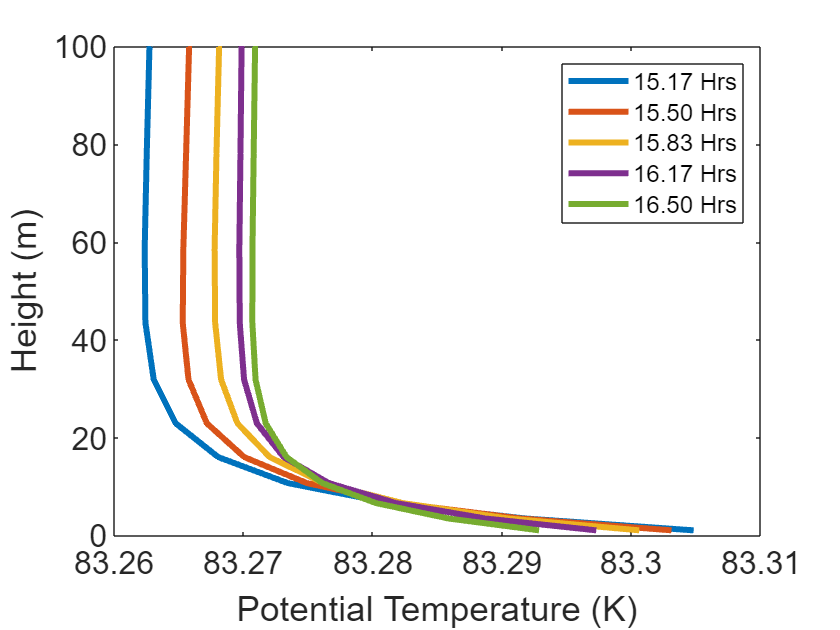

size=16;
for i=20:1:24
    numero=8.5+(i.*(1/3));
    numero=string(sprintf('%.2f', numero));
    plot(tt(:,i)',ejez,'DisplayName',strcat(numero,' Hrs'),'LineWidth',3);
    hold on
end 
    ylim([0 100]);
    % xlim([0 0.01]);
    % ax.ColorOrder = colors_p;
    % ax.Color = 'c';
    ylabel('Height (m)')
    xlabel('Potential Temperature (K)')
    % title('Velocity (mean U)')
    legend('-DynamicLegend',"AutoUpdate","on",'Location','northeast','FontSize',12);
    % saveas(gca,'SHprom.png');
ax = gca;  % Obtiene el objeto de los ejes actuales
ax.XAxis.FontSize = size;  % Cambia el tamaño de los números del eje X
ax.YAxis.FontSize = size;  % Cambia el tamaño de los números del eje y
hold off

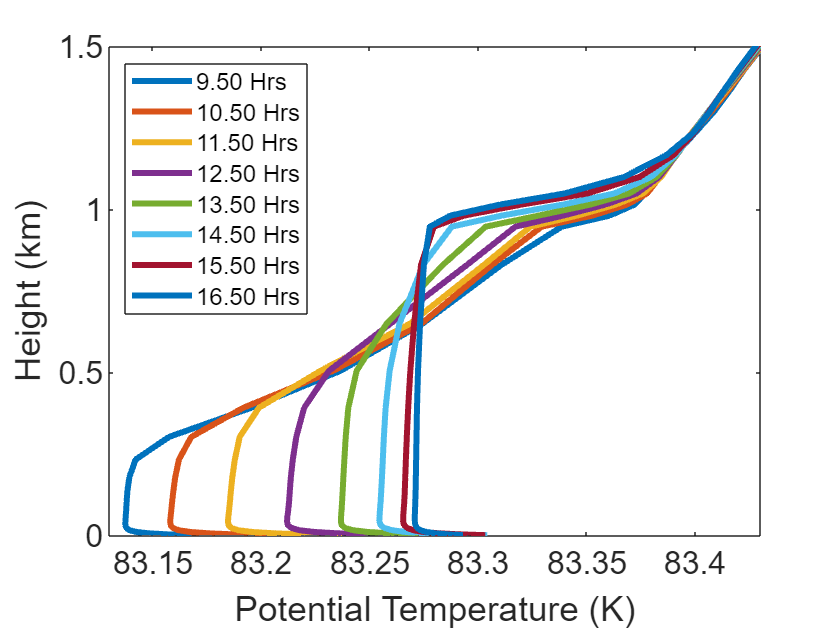

size=16;
for i=3:3:24
    numero=8.5+(i.*(1/3));
    numero=string(sprintf('%.2f', numero));
    plot(tt(:,i)',ejez./1000,'DisplayName',strcat(numero,' Hrs'),'LineWidth',3);
    hold on
end 
    ylim([0 1.5]);
    xlim([83.13 83.43]);
    % ax.ColorOrder = colors_p;
    % ax.Color = 'c';
    ylabel('Height (km)')
    xlabel('Potential Temperature (K)')
    % title('Velocity (mean U)')
    legend('-DynamicLegend',"AutoUpdate","on",'Location','northwest','FontSize',12);
    % saveas(gca,'SHprom.png');
ax = gca;  % Obtiene el objeto de los ejes actuales
ax.XAxis.FontSize = size;  % Cambia el tamaño de los números del eje X
ax.YAxis.FontSize = size;  % Cambia el tamaño de los números del eje y
hold off